clear;
clc;
close all;

load('data1.mat')

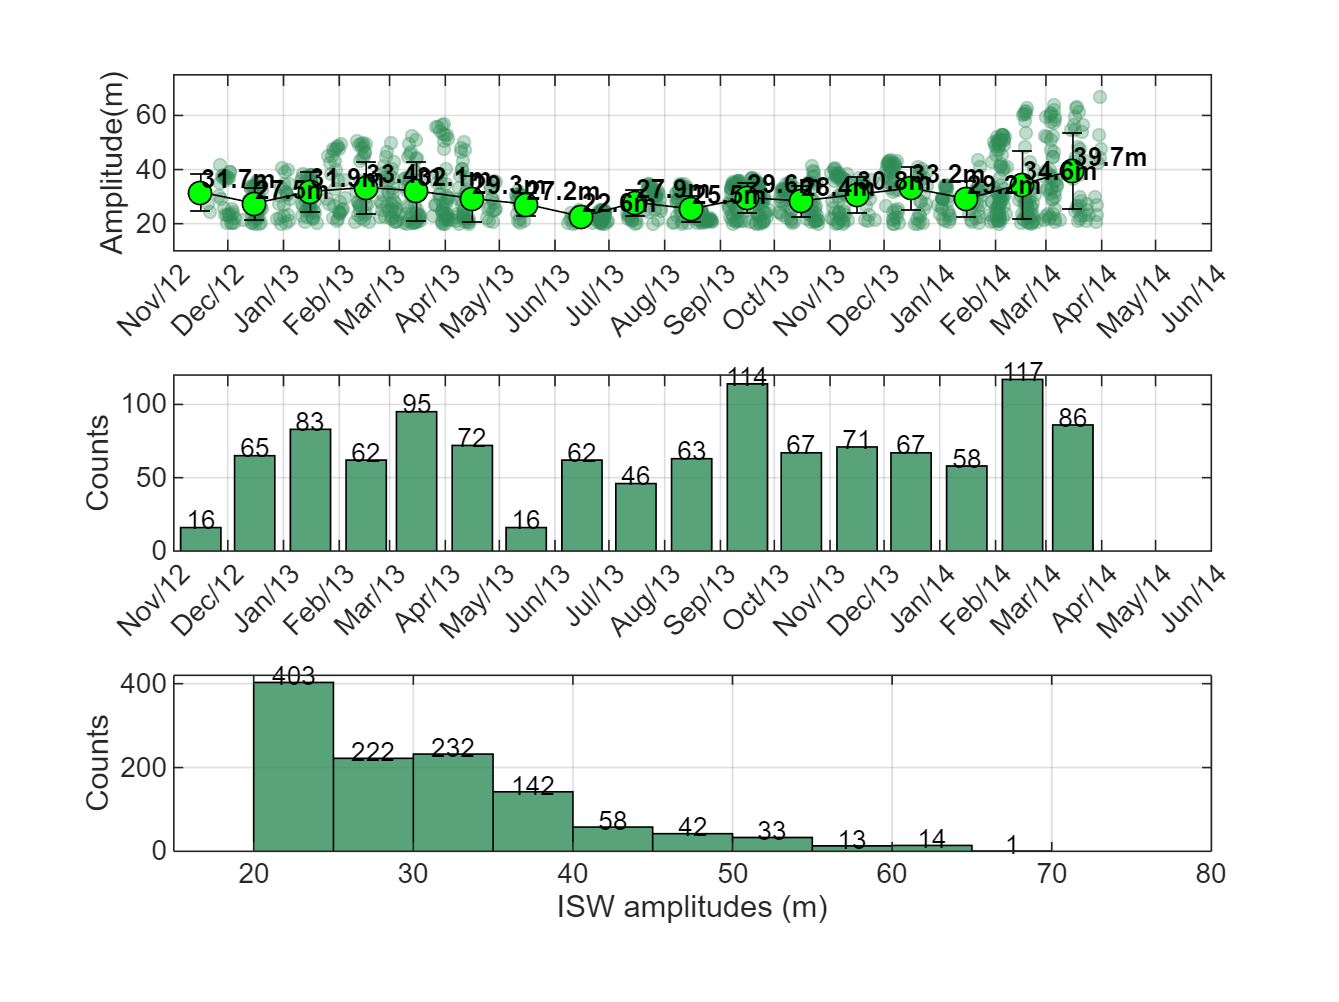



figure(1)
subplot(3,1,1)

scatter(isw_time_ind,iswamp1,15,'markerfacecolor',[0.18 0.55 0.34],'markeredgecolor',[0.18 0.55 0.34]...
    ,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3)
hold on
errorbar(monthlyDatenums+15,avgamp1,stdamp1,'o','Color','k')
ylabel('Amplitude(m)')
hold on;grid on;box on;
plot(monthlyDatenums+15,avgamp1,'k-o','MarkerFaceColor','g','MarkerSize',7)
for ii = 1:36
    text(monthlyDatenums(ii)+15,avgamp1(ii)+5,[num2str(round(avgamp1(ii),1)),'m'],...
        'FontSize',8,'FontWeight','bold')
end
xticks(monthlyDatenums);
datetick('x','mmm/yy', 'keepticks')
xlim([735174 735751])
grid on
ylim([10,75])

subplot(3,1,2)
bar(monthlyDatenums+15,ampnum1,'facecolor',[0.18 0.55 0.34],'FaceAlpha',0.8)
xticks(monthlyDatenums);
datetick('x','mmm/yy', 'keepticks')
grid on;

xlim([735174 735751])
ylim([0,120])

ylabel('Counts')
grid on

for ii = 1:length(ampnum1)
    if ampnum1(ii)>0
        text(monthlyDatenums(ii)+15, ampnum1(ii)+5, num2str(ampnum1(ii)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8);
    end
end

subplot(3,1,3)

edges = 20:5:80;
[N, ~] = histcounts(iswamp1, edges); % 获取频数
histogram(iswamp1,edges,'FaceColor',[0.18 0.55 0.34],'FaceAlpha',0.8)
grid on
xlim([15 80])
ylim([0 420])
xlabel('ISW amplitudes (m)')
ylabel('Counts')
% 添加数字标签
binCenters = (edges(1:end-1) + edges(2:end)) / 2; % 计算柱子中心位置
for ii = 1:length(N)
    if N(ii) > 0 % 只标注非零柱子
        text(binCenters(ii), N(ii)+15, num2str(N(ii)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8);
    end
end

load('data2.mat')

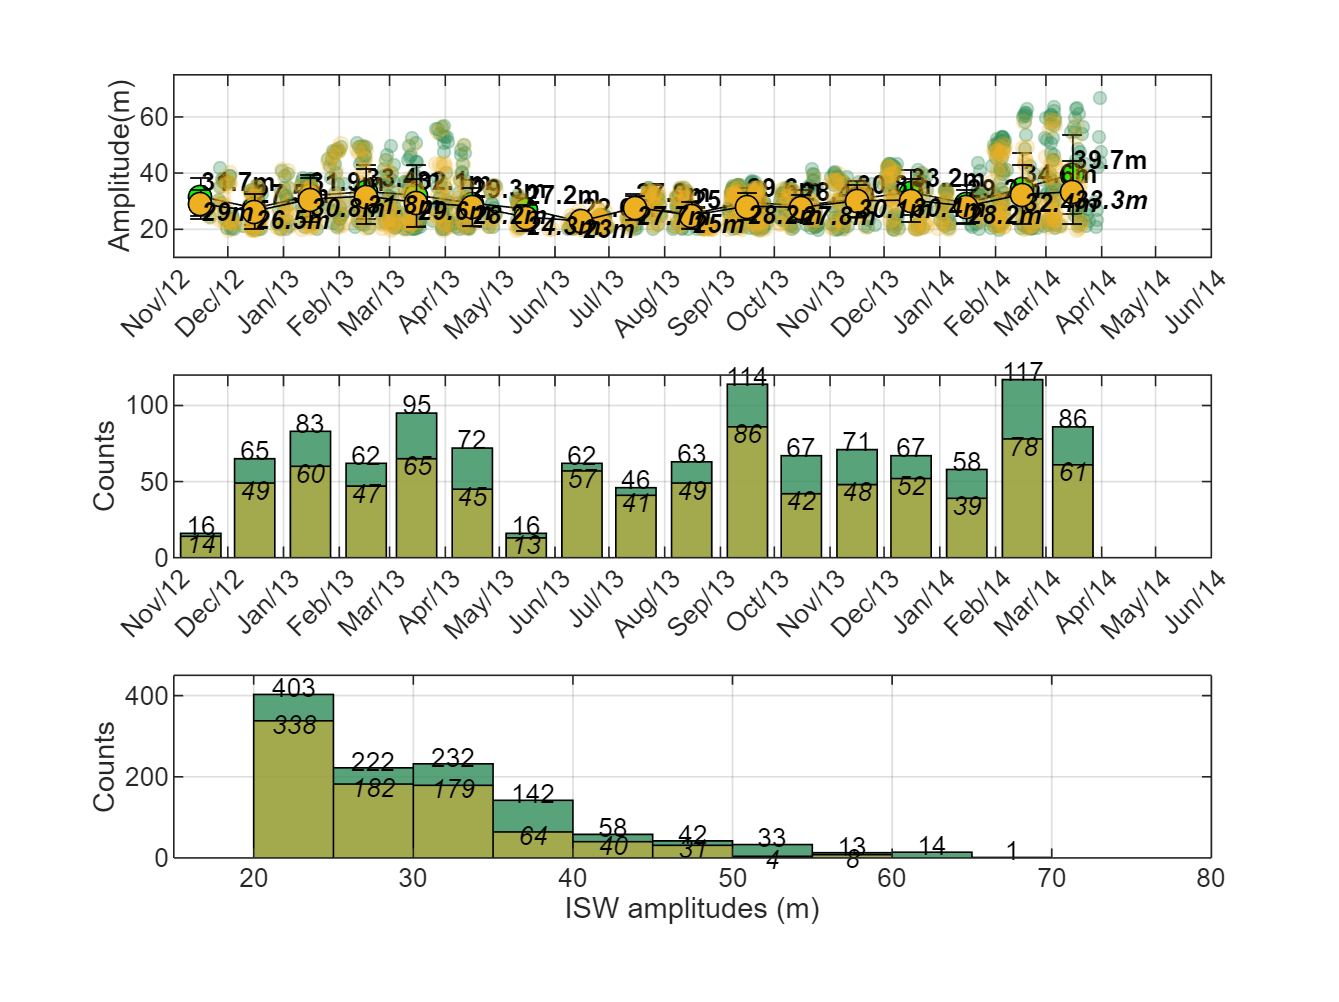



figure(1)
subplot(3,1,1)
hold on
scatter(isw_time_ind,iswamp2,20,'markerfacecolor',[0.93,0.69,0.13],'markeredgecolor',[0.93,0.69,0.13]...
    ,'MarkerFaceAlpha',0.2,'MarkeredgeAlpha',0.2)
hold on
errorbar(monthlyDatenums+15,avgamp2,stdamp2,'o','Color','k')
ylabel('Amplitude(m)')
hold on;grid on;box on;
plot(monthlyDatenums+15,avgamp2,'k-o','MarkerFaceColor',[0.93,0.69,0.13],'MarkerSize',7)
for ii = 1:36
    text(monthlyDatenums(ii)+15,avgamp2(ii)-3,[num2str(round(avgamp2(ii),1)),'m'],'FontSize',8,...
        'FontAngle','italic','FontWeight','bold')
end
xticks(monthlyDatenums);
datetick('x','mmm/yy', 'keepticks')
xlim([735174 735751])
grid on
ylim([10,75])
set(gca, 'XTickLabel', get(gca, 'XTickLabel'), 'FontSize', 8);
subplot(3,1,2)
hold on
bar(monthlyDatenums+15,ampnum2,'facecolor',[0.93,0.69,0.13],'FaceAlpha',0.5)
xticks(monthlyDatenums);
datetick('x','mmm/yy', 'keepticks')
grid on;

xlim([735174 735751])
ylim([0,120])
ylabel('Counts')
grid on
for ii = 1:length(ampnum2)
    if ampnum2(ii)>0
        text(monthlyDatenums(ii)+15, ampnum2(ii)-5, num2str(ampnum2(ii)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8,'FontAngle','italic');
    end
end
set(gca, 'XTickLabel', get(gca, 'XTickLabel'), 'FontSize', 8);
subplot(3,1,3)
hold on
edges = 20:5:80;
[N, ~] = histcounts(iswamp2, edges);
histogram(iswamp2,edges,'FaceColor',[0.93,0.69,0.13],'FaceAlpha',0.5)
grid on
xlim([15 80])
ylim([0 450])
xlabel('ISW amplitudes (m)')
ylabel('Counts')

binCenters = (edges(1:end-1) + edges(2:end)) / 2;
for ii = 1:length(N)
    if N(ii) > 0
        text(binCenters(ii), N(ii)-10, num2str(N(ii)), ...
            'HorizontalAlignment', 'center', 'FontSize', 8,'FontAngle','italic');
    end
end
set(gca, 'XTickLabel', get(gca, 'XTickLabel'), 'FontSize', 8);